%Mercury
CWIN = [5, 10, 30, 45, 60, 90, 120, 160, 200, 240, 300, 360, 420, 500, 600, 1000, 1500, 2000, 2500, 3000, 3500, 4000, 4500, 5000];
n_tuple_mercury = [5880,4283,2436,1835,1428,928,725,594,508,476,453,440,430,421,410,378,331,310,290,278,266,257,247,241];
plot(CWIN,n_tuple_mercury,CWIN,n_tuple_mercury,'*')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%360
saveas(gcf,'tupleCountMercury','png');

%bgl 
n_tuple_bgl=[918,681,484,474,471,428,421,410,403,399,385,375,369,356,348,326,304,290,281,264,253,244,234,228];
 plot(CWIN,n_tuple_bgl,CWIN,n_tuple_bgl,'*')
xlabel('Dimensione della finestra (s)')
ylabel('Numero di tuple')
grid on
%420
saveas(gcf,'tupleCountBLG','png');

id = fopen("/Users/marcoriccio/Documents/Gruppo15/Homework-IE-18-19/5/design/ffdatoolsetIE2016/tupling_MercuryErrorLog-360/interarrivals.txt");
intarrivals = fscanf(id,'%d');
[p,t]=cdfcalc(intarrivals);
ttf=p(2:size(p,1));
rel = 1-ttf;

subplot(2,2,1)
plot(t,ttf,'--',t,rel,':r','LineWidth',2);
xlabel('Tempo (s)')
ylabel('p')
grid on
title('CDF Empirica');

%Esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.352131586294421 -2.22768270295095e-05];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

%plot Esponenziale
subplot(2,2,2);
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Esponenziale')

%Iper_esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1.29618063668875 -2.81249338835857e-05 -0.691281124730794 -2.10979088537547e-05];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot Iper-esponenziale
subplot(2,2,3)
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Iper-Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Iper-esponenziale')

%Weibull
%Calcolo di 1 / mean(TTF)
n=length(ttf)
sum=0;
for i=1:n
    sum=sum+ttf(i);
end
ttf_mean=sum/n;
l=1/ttf_mean;

[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp(-(l*x)^a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.5 0.00001];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot Weibull
subplot(2,2,4)
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Weibull', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Weibull')
saveas(gcf,'ReliabilityEs1','png')

id = fopen("/Users/marcoriccio/Documents/Gruppo15/Homework-IE-18-19/5/design/ffdatoolsetIE2016/tupling_BGLErrorLog-420/interarrivals.txt");
intarrivals = fscanf(id,'%d');
[p,t]=cdfcalc(intarrivals);
ttf=p(2:size(p,1));
rel = 1-ttf;

subplot(2,2,1)
plot(t,ttf,'--',t,rel,':r','LineWidth',2);
xlabel('Tempo (s)')
ylabel('p')
grid on
title('CDF Empirica');

%Esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.352131586294421 -2.22768270295095e-05];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

%plot Esponenziale
subplot(2,2,2);
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Esponenziale')

%Iper_esponenziale
[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1.29618063668875 -2.81249338835857e-05 -0.691281124730794 -2.10979088537547e-05];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot Iper-esponenziale
subplot(2,2,3)
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Iper-Exponential', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Iper-esponenziale')

%Weibull
%Calcolo di 1 / mean(TTF)
n=length(ttf)

n = 364

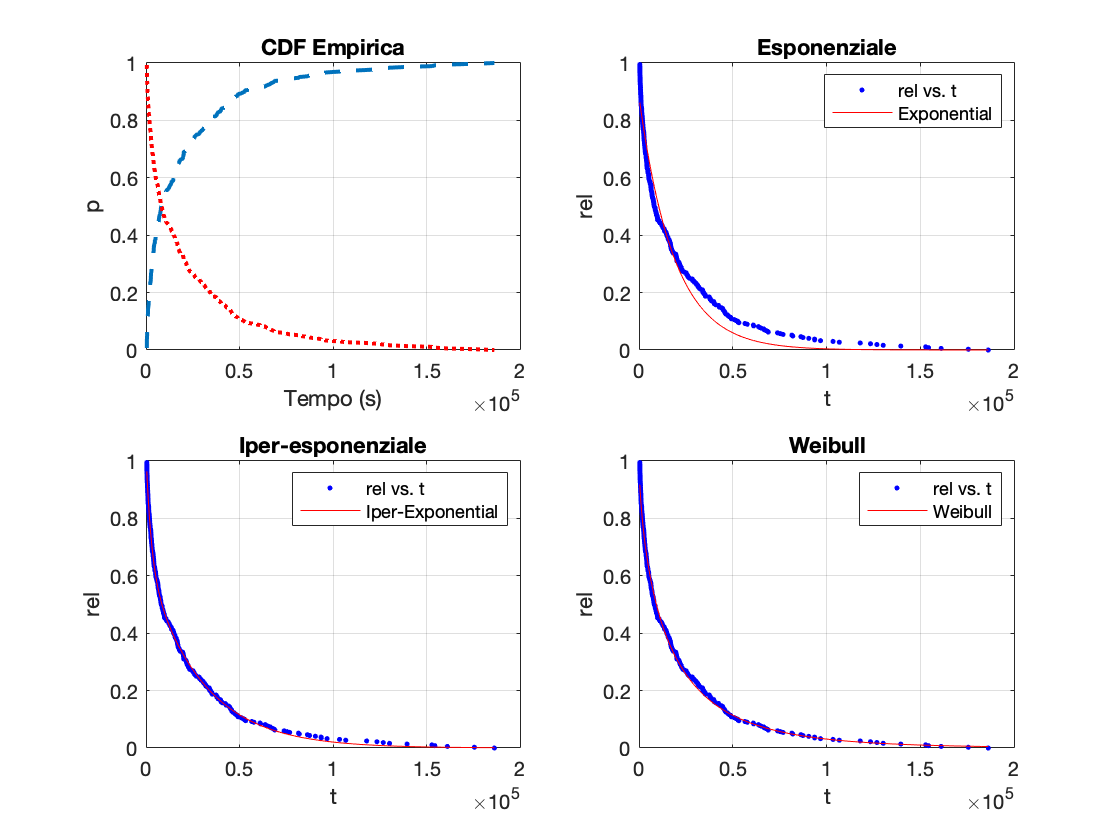

sum=0;
for i=1:n
    sum=sum+ttf(i);
end
ttf_mean=sum/n;
l=1/ttf_mean;

[xData, yData] = prepareCurveData( t, rel );
% Set up fittype and options.
ft = fittype( 'exp(-(l*x)^a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.5 0.00001];
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot Weibull
subplot(2,2,4)
h = plot( fitresult, xData, yData );
legend( h, 'rel vs. t', 'Weibull', 'Location', 'NorthEast' );
% Label axes
xlabel t
ylabel rel
grid on
title('Weibull')
saveas(gcf,'ReliabilityEs1bgl','png')